## Controlador final

### PID

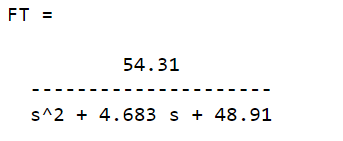

clear
s=tf('s');


num=[54.31]

num = 54.3100

den=[1 4.683 48.91]

den =     1.0000    4.6830   48.9100



roots(den)

ans =   -2.3415 + 6.5899i
  -2.3415 - 6.5899i


x=cos(linspace(0, 2*pi, 1000));
y=sin(linspace(0, 2*pi, 1000));

G=tf(num,den)

G =
 
          54.31
  ---------------------
  s^2 + 4.683 s + 48.91
 
Continuous-time transfer function.



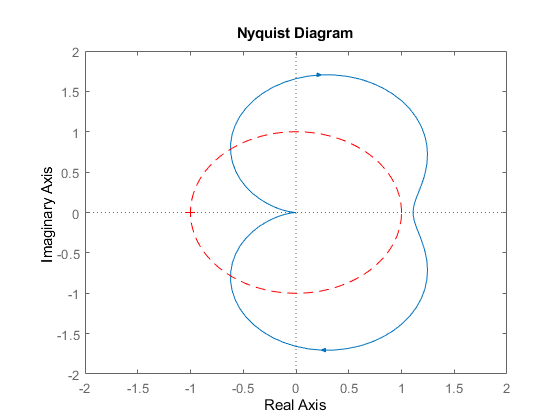

figure
nyquist(G)
hold on
plot(x,y ,'r--'); %// Unit circle
hold off
xlim([-2 2])

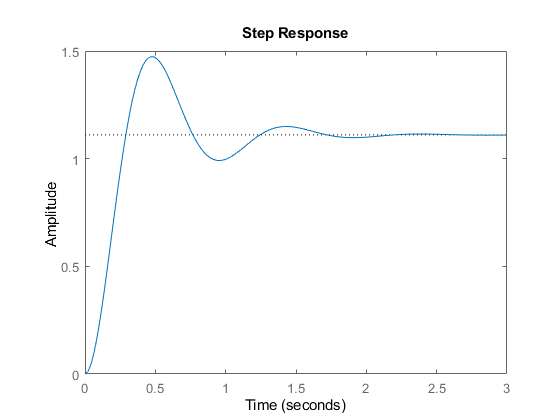

figure
step(G)

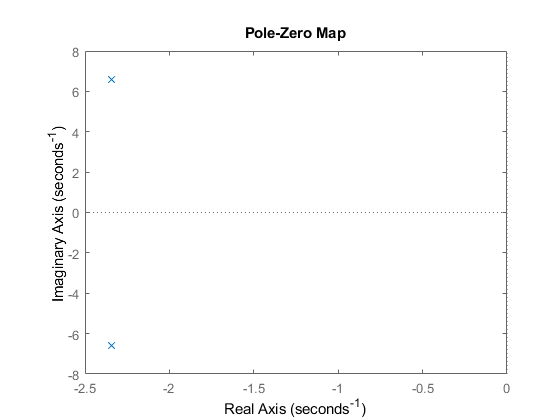

figure
pzmap(G)


syms zeta
assume(zeta>0)
Mp=0.5;
ts=15;
a=-4.5/ts;



Fsobrepico=Mp==exp(-pi*zeta/(sqrt(1-zeta^2)))

$$Fsobrepico = \frac{1}{2}={\mathrm{e}}^{-\frac{\pi \,\zeta }{\sqrt{1-\zeta^{2}}}}$$

zetaS=solve(Fsobrepico,zeta);

zeta=double(zetaS);
r_tr=-1.8/(a/zeta)

r_tr = 1.2927

AngZeta=acos(zeta);
xline=a+(-10:1:10)*1i;

### Diseño PID

Iterar k_i

syms S k_i_s k_s k_d_s
Den=poly2sym(den,S)

$$Den = S^{2}+\frac{4683\,S}{1000}+\frac{4891}{100}$$

%N=1000
G_S=num/Den;
%C=k_i_s/S+k_s+k_d_s*N/(1+N/S)
C=k_i_s/S+k_s+k_d_s

$$C = k_{d,s}+k_{s}+\frac{k_{i,s}}{S}$$

Go=collect(C*G_S/(1+C*G_S),S)

$$Go = \frac{\left(54310\,k_{d,s}+54310\,k_{s}\right)\,S+54310\,k_{i,s}}{1000\,S^{3}+4683\,S^{2}+\left(54310\,k_{d,s}+54310\,k_{s}+48910\right)\,S+54310\,k_{i,s}}$$

[Num,Den]=numden(Go)

$$Num = 54310\,k_{i,s}+54310\,S\,k_{d,s}+54310\,S\,k_{s}$$

$$Den = 48910\,S+54310\,k_{i,s}+54310\,S\,k_{d,s}+54310\,S\,k_{s}+4683\,S^{2}+1000\,S^{3}$$

### Iteración k_i

tff=collect(-(solve(Den,k_i_s))^-1,S)

$$tff = \frac{54310}{1000\,S^{3}+4683\,S^{2}+\left(54310\,k_{d,s}+54310\,k_{s}+48910\right)\,S}$$

[Num,Den]=numden(tff)

$$Num = 54310$$

$$Den = 48910\,S+54310\,S\,k_{d,s}+54310\,S\,k_{s}+4683\,S^{2}+1000\,S^{3}$$



CoefDen=coeffs(Den,S);
CoefNum=coeffs(Num,S);
CoefNum=fliplr(CoefNum/CoefDen(end));
CoefDen(k_s,k_d_s)=fliplr(CoefDen/CoefDen(end))

$$CoefDen(k\_s, k\_d\_s) = \left(\begin{array}{ccc} 1 & \frac{4683}{1000} & \frac{5431\,k_{d,s}}{100}+\frac{5431\,k_{s}}{100}+\frac{4891}{100} \end{array}\right)$$


k=0.175

k = 0.1750

k_d=0.001

k_d = 1.0000e-03


CoefNum=double(CoefNum)

CoefNum = 54.3100

CoefDen=double(CoefDen(k,k_d))

CoefDen =     1.0000    4.6830   58.4686



sVden=[s^3 s^2 s];
SArrayDen=CoefDen.*sVden;

G_rl=(CoefNum(1))/(SArrayDen(1)+SArrayDen(2)+SArrayDen(3))

G_rl =
 
            54.31
  -------------------------
  s^3 + 4.683 s^2 + 58.47 s
 
Continuous-time transfer function.



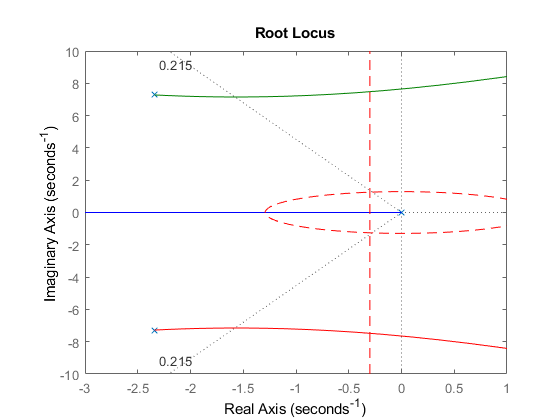


figure
rlocus(G_rl)
sgrid(zeta,20)
hold on
plot(xline,'r--')
plot(x*r_tr,y*r_tr,'r--')
xlim([-3 1])
ylim([-10 10])
hold off

### Resultados PID

k_i=1.5

k_i = 1.5000

k=0.175

k = 0.1750

k_d=0.001

k_d = 1.0000e-03

N=1000

N = 1000


C=k_i/s+k+k_d*N/(1+N/s)

C =
 
  1.175 s^2 + 176.5 s + 1500
  --------------------------
         s^2 + 1000 s
 
Continuous-time transfer function.



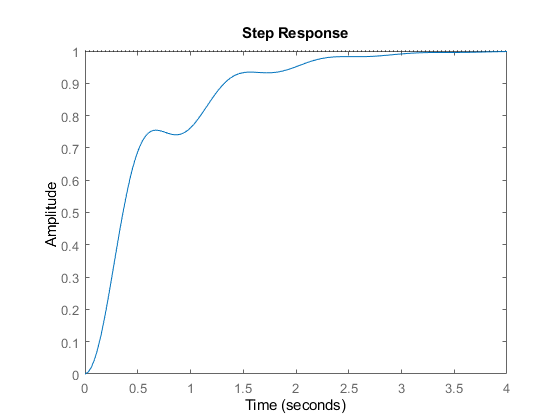


Go=feedback(C*G,1);
figure
step(Go)

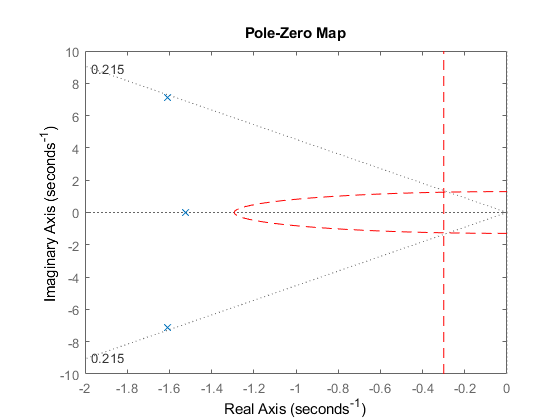

figure
pzmap(Go)
sgrid(zeta,20)
hold on
plot(xline,'r--')
plot(x*r_tr,y*r_tr,'r--')
xlim([-2 0])
hold off


PolosPID=pole(Go)

PolosPID = 	1.0e+02 *

  -9.9995 + 0.0000i
  -0.0161 + 0.0714i
  -0.0161 - 0.0714i
  -0.0152 + 0.0000i




G_pid=G*C

G_pid =
 
      63.81 s^2 + 9586 s + 81465
  -----------------------------------
  s^4 + 1005 s^3 + 4732 s^2 + 48910 s
 
Continuous-time transfer function.



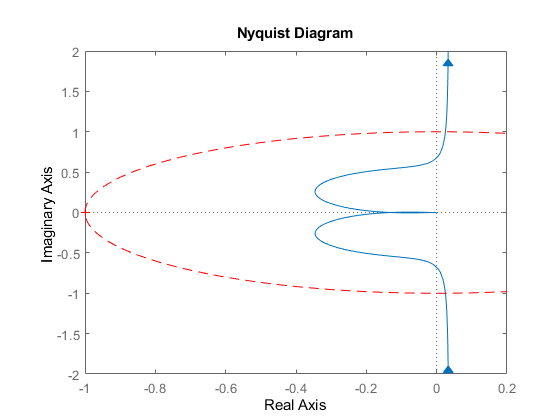


figure
nyquist(G_pid)

%xlim([-1.5,-0.5])
ylim([-2,2])
hold on
plot(x, y,'r--'); %// Unit circle
hold off

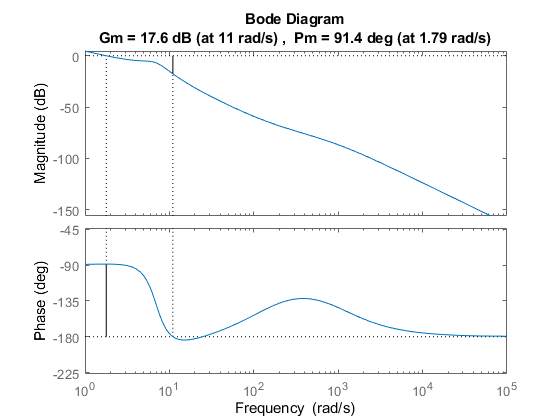

figure
margin(G_pid)

G

G =
 
          54.31
  ---------------------
  s^2 + 4.683 s + 48.91
 
Continuous-time transfer function.



G_pid

G_pid =
 
      63.81 s^2 + 9586 s + 81465
  -----------------------------------
  s^4 + 1005 s^3 + 4732 s^2 + 48910 s
 
Continuous-time transfer function.



[num2,den2]=tfdata(G_pid);
num2=num2{1};
den2=den2{1};

PIDdiscreto=c2d(C,0.002,'tustin')

PIDdiscreto =
 
  0.6765 z^2 - 1.173 z + 0.5
  --------------------------
           z^2 - z
 
Sample time: 0.002 seconds
Discrete-time transfer function.

